Generar mapas que se utilizarán luego

clear;clc;close all
layerfolder='../data/layers/';%Route to folder with ambiental data
Dimensions = ReadLayers(layerfolder); %The 19 environmental variables for all the map

----Reading layers----
Elapsed time is 7.927125 seconds.


nmaps=10;
InfoInitialPoint = cell(1,nmaps);
for i=1:nmaps
    InfoInitialPoint{i} = InitialPoint(Dimensions);
end

Elapsed time is 8.343513 seconds.
Elapsed time is 8.720702 seconds.
Elapsed time is 9.522438 seconds.
Elapsed time is 7.902096 seconds.
Elapsed time is 7.855042 seconds.
Elapsed time is 7.928553 seconds.
Elapsed time is 7.836103 seconds.
Elapsed time is 7.910179 seconds.
Elapsed time is 7.894367 seconds.
Elapsed time is 7.847034 seconds.


opt=struct;
opt.Dimensions=Dimensions;
opt.InfoInitialPoint=InfoInitialPoint;

nominal = [1 0.5 100 -3 1 25];


ParNames =  {'map','occ','nsamples','factor', 'alpha', 'percentile'};
VarNames = {};
OutNames = {'metric1','metric2'};

FullNames = [VarNames,ParNames];
RangeT = [1 nmaps;0.1 0.9;20 500;-5 0; 0 1; 0 50];

T = gsua_dataprep("gsua_connect",RangeT,'nominal',nominal, 'domain',[0 2], 'names',...
        FullNames, 'out_names', OutNames,'opt',opt);

Setting environment to work with user-defined function


percentile = 25

----Finding correlation----
Elapsed time is 2.137600 seconds.
----Creating predictors----
¡All done!
Elapsed time is 2.721985 seconds.
----Modeling----


ij = 1

-Model 1
Elapsed time is 0.797383 seconds.


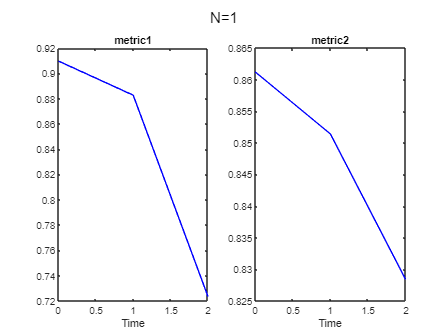

gsua_eval(T.Nominal,T); 

M = gsua_dmatrix(T,100);
M

M =     2.8222    0.4540  368.9363   -0.1491    0.2649   12.4883
    8.9673    0.6622  329.5424   -1.1070    0.5912   23.7325
    6.0143    0.2035  246.0006   -2.6940    0.2002   34.9292
    2.4915    0.3325  381.0774   -4.1455    0.7786   49.0364
    8.2519    0.1942  400.3550   -2.4145    0.8382   38.8359
    2.9375    0.6382  145.7325   -0.0781    0.3286    5.9686
    7.2468    0.7730  289.7585   -2.3232    0.5275   21.5301
    6.7989    0.5704  406.2071   -3.2969    0.0882   48.1900
    1.6891    0.7535  243.9934   -2.0013    0.5579   28.9379
    5.1026    0.3456  471.0000   -0.1922    0.8575   42.8706


T.Properties.CustomProperties.output = 1;
%3.2. Sensibility analysis
Tsa = gsua_sa(M,T, 'SensMethod', 'Xiao');

----Finding correlation----
Elapsed time is 1.306394 seconds.
----Creating predictors----
¡All done!
Elapsed time is 1.400566 seconds.
----Modeling----


ij = 1

-Model 1
Elapsed time is 0.519030 seconds.
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
Using only the first 18 components to compute TSQUARED.
> In pca>localTSquared (line 515)
In pca (line 361)
In 

Index exceeds the number of array elements. Index must not exceed 306593.

Error in NicheGeneration (line 38)
    SortNormDistance(IndexSortNorm) = normalize(SortNormDistance(IndexSortNorm), 2, 'range');

Error in gsua_connect (


%3.3. Confiabilidad

c = sum(Tsa.Si)/sum(abs(Tsa.Si))